% Plot the elastic energy during deployment with the deployment of whole
triangle = opt_tessellation{30};
triangle_target = opt_tessellation_target{30};
n = 100;
i = 0;
E_rotation = zeros(n,1)

E_rotation =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


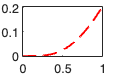

index = [23,36,37;
    33,37,36;
    19,32,33;
    41,33,32;
    27,40,41;
    37,41,40]; % Index to calculate the rotational energy in springs

k_r = 1; % Rotational stiffness of a single spring

for alpha = 0:1/n:1
    i = i+1;
    x_deploy = (1-alpha) * triangle(:,1) + alpha * triangle(:,1);
    y_deploy = (1-alpha) * triangle(:,2) + alpha * triangle(:,2);
    z_deploy = alpha * triangle_target(:,3);
    triangle_deploy = [x_deploy, y_deploy, z_deploy];
    for j = 1:size(index,1)
        angle_diff(j) = angle_calculate(triangle_deploy(index(j,:),:)) - ...
            angle_calculate(triangle(index(j,:),:));
    end
    E_rotation(i) = sum(1/2 * k_r * angle_diff.^2);
end

alpha_values = linspace(0, 1, n+1);

figure('Name','Energy Curve','Position',[200 200 900 600]);
plot(alpha_values, E_rotation, 'r--', 'LineWidth', 1.5, 'DisplayName', 'In-plane Energy');